#  Fitting Propagation Models from Ray Tracing Data

## Loading the data

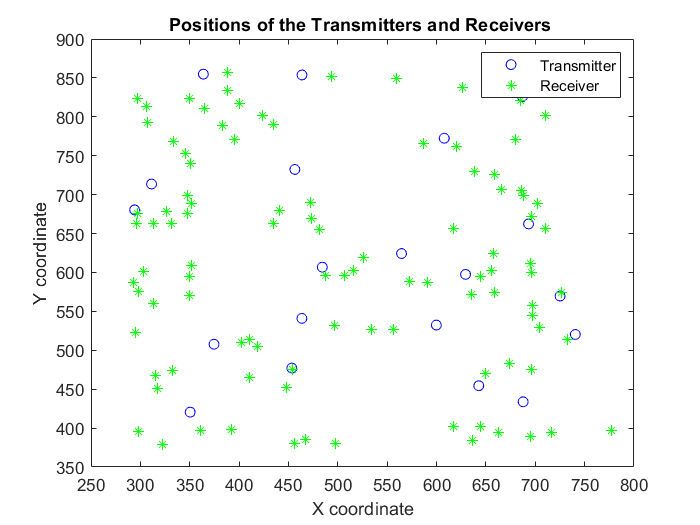

load pathData;



nrx = length(rxpos);
ntx = length(txpos);
npath = height(pathTable);

% Plotting the locations  of the TX and RX on the x-y plane.
x_tx = txpos(:,1);
y_tx = txpos(:,2);

x_rx = rxpos(:,1);
y_rx = rxpos(:,2);

figure;

plot(y_tx,x_tx,"LineStyle","none","Marker","o","Color",'b')
hold on 
plot(y_rx,x_rx,"LineStyle","none","Marker","*","Color","g")
hold off
title("Positions of the Transmitters and Receivers ")
legend("Transmitter","Receiver")
xlim([250 800])
ylim([350 900])
xlabel("X coordinate")
ylabel("Y coordinate")

## Determining  omni-directional path loss and minimum path delay


head(pathTable,4)

ans = 4×9 table
    TXID    RXID    rx_power_dbm    Phase_deg     toa_sec      doa_theta_deg    doa_phi_deg    aoa_theta_deg    aoa_phi_deg
    ____    ____    ____________    _________    __________    _____________    ___________    _____________    ___________

     1       1        -36.444        -39.827     1.6711e-07        85.51          34.222           94.49          -145.78  
     1       1        -39.774         93.772     1.7921e-07       85.813          40.727          94.187           150.77  
     1       1        -43.031         152.01     1.6815e-07       96.635          34.707          98.116          -145.94  
     1       1        -45.614        -30.955     1.8011e-


pathExists = zeros(nrx,ntx);
totRx = zeros(nrx,ntx);
minDLY = zeros(nrx,ntx);

for k = 1:npath
        rxid = pathTable(k,"RXID").Variables;
        txid = pathTable(k,"TXID").Variables;
    
        pathExists(rxid,txid) = 1;
        totRx(rxid,txid) = totRx(rxid,txid) + db2pow(pathTable(k,"rx_power_dbm").Variables);
        minDLY(rxid,txid) = min(minDLY(rxid,txid),pathTable(k,"toa_sec").Variables);
    
    
end
       
% calculating the omni-directiona path loss 

txPowdBm = 36;
pl_omni = txPowdBm - pow2db(totRx);

## Ploting  the path loss vs. distance

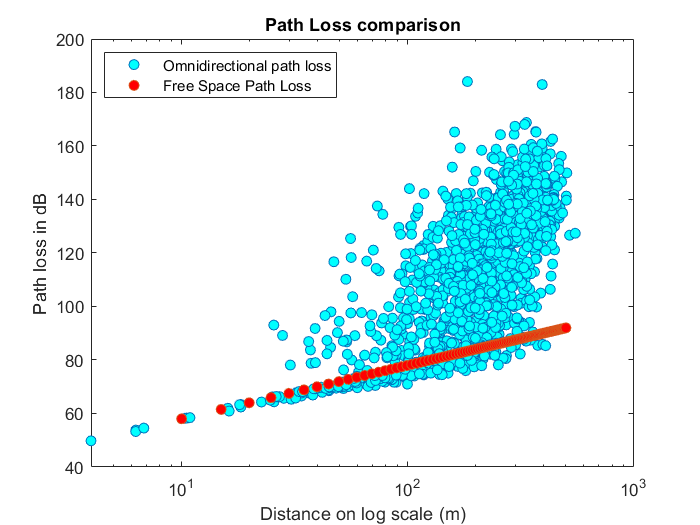


dist = sqrt(sum((permute(rxpos, [1 3 2]) - permute(txpos, [3 1 2])) .^ 2, 3));


dist1 = reshape(dist,nrx*ntx,1);

pl_omni1 = reshape(pl_omni,ntx*nrx,1);

minDly1 = reshape(minDLY,ntx*nrx,1);

pathExists1 = reshape(pathExists,ntx*nrx,1);

%  Computing  the free-space path loss for 100 points from dmin to dmax.

dmin = 10;
dmax = 500;
fc = 1.9e9; % Carrier frequency
c = physconst('lightspeed');
r = dmin: (dmax-dmin)/99 : dmax;

FSPL = fspl(r,c/fc);


figure;

semilogx(dist1,pl_omni1,"LineStyle","none","Marker","o",'MarkerFaceColor',"c")
hold on 
semilogx(r,FSPL,"LineStyle","none","Marker","o",'MarkerFaceColor',"r")
hold off
legend('Omnidirectional path loss','Free Space Path Loss',"Location","northwest")
title("Path Loss comparison")
xlabel("Distance on log scale (m)")
ylabel("Path loss in dB")

## Classify points as LOS , NLOS and Outage



outage = 0;
losLink = 1;
nlosLink = 2;


linkstate = 3*ones(2000,1);  % creating an empty matrix with different numbers 

%filling the matrix with the required tokens

linkstate(pathExists1 == 0) = outage;
linkstate((dist1/c - minDly1)>1e-7 & linkstate ~= outage) = nlosLink;
linkstate((dist1/c - minDly1)<1e-7 & linkstate ~= outage) = losLink;


% Printing  the fraction of the links in each of the three states

outage_n = 0;
nlos_n = 0 ;
los_n =0 ;

for i = 1:2000
    if linkstate(i) == outage 
        outage_n = outage_n +1;
    elseif linkstate(i) == nlosLink
        nlos_n = nlos_n +1;
    elseif linkstate(i) == losLink
        los_n = los_n +1;
    end
end

fprintf('Percentage of links in Outage is  %2.2f',outage_n*100/(outage_n+nlos_n+los_n))

Percentage of links in Outage is  28.55

fprintf('Percentage of links in LOS is  %2.2f',los_n*100/(outage_n+nlos_n+los_n))

Percentage of links in LOS is  1.10

fprintf('Percentage of links in NLOS is  %2.2f',nlos_n*100/(outage_n+nlos_n+los_n))

Percentage of links in NLOS is  70.35

##  path loss vs. distance for the NLOS and LOS links

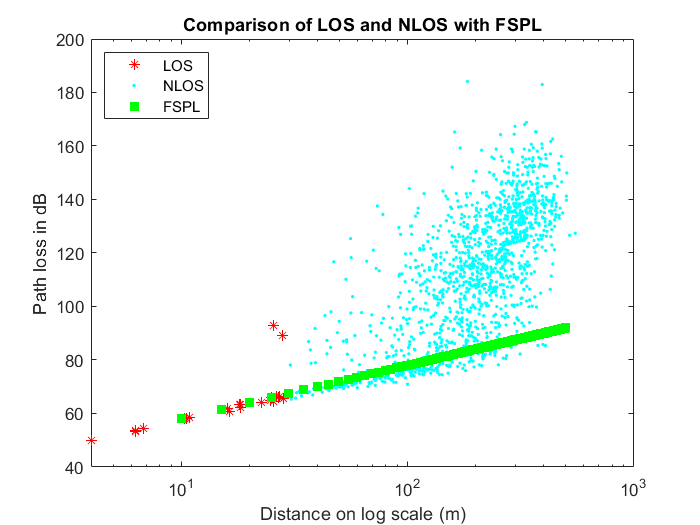

figure ;

semilogx(dist1(linkstate == losLink),pl_omni1(linkstate == losLink),'LineStyle',"none","Marker","*","Color","r")
hold on 
semilogx(dist1(linkstate == nlosLink),pl_omni1(linkstate == nlosLink),'LineStyle',"none","Marker",".","Color","c")
semilogx(r,FSPL,"LineStyle","none","Marker","square","MarkerEdgeColor","g","MarkerFaceColor","g")
hold off
title("Comparison of LOS and NLOS with FSPL")
legend("LOS","NLOS","FSPL","Location","northwest")
xlabel("Distance on log scale (m)")
ylabel("Path loss in dB")

## Linear fit for the path loss model

Fitting to the linear model



y_los = pl_omni1(linkstate == losLink);
x_los = 10*log10(dist1(linkstate == losLink));

% using the matlab function 

% for los 
model_los = fitlm(x_los,y_los);
a_los = model_los.Coefficients(1,"Estimate").Variables;
b_los = model_los.Coefficients(2,"Estimate").Variables;
sig = sqrt(model_los.MSE);

fprintf('The parameters a,b and sigma for LOS model are %2.2f, %2.2f and %2.2f respectively',a_los,b_los,sig)

The parameters a,b and sigma for LOS model are 30.81, 2.75 and 7.34 respectively


%for NLOS
y_nlos = pl_omni1(linkstate == nlosLink);
x_nlos = 10*log10(dist1(linkstate == nlosLink));

model_nlos = fitlm(x_nlos,y_nlos);
a_nlos = model_nlos.Coefficients(1,"Estimate").Variables;
b_nlos = model_nlos.Coefficients(2,"Estimate").Variables;
sig = sqrt(model_nlos.MSE);

fprintf('The parameters a,b and sigma for NLOS model are %2.2f, %2.2f and %2.2f respectively',a_nlos,b_nlos,sig)

The parameters a,b and sigma for NLOS model are -41.99, 6.74 and 17.55 respectively

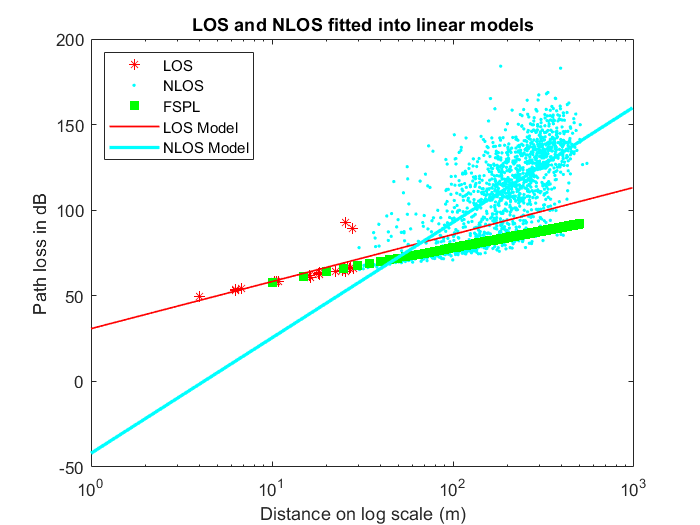




distance = 1:20:1000;
los_model = a_los + b_los*10*log10(distance) ;
nlos_model = a_nlos + b_nlos*10*log10(distance) ;

figure ;

semilogx(dist1(linkstate == losLink),pl_omni1(linkstate == losLink),'LineStyle',"none","Marker","*","Color","r")
hold on 
semilogx(dist1(linkstate == nlosLink),pl_omni1(linkstate == nlosLink),'LineStyle',"none","Marker",".","Color","c")
semilogx(r,FSPL,"LineStyle","none","Marker","square","MarkerEdgeColor","g","MarkerFaceColor","g")
hold on
semilogx(distance,los_model,"LineWidth",1,"color",'r')
semilogx(distance,nlos_model,"LineWidth",2,"Color",'c')

title("LOS and NLOS fitted into linear models")
legend("LOS","NLOS","FSPL","LOS Model","NLOS Model","Location","northwest")
xlabel("Distance on log scale (m)")
ylabel("Path loss in dB")

## Plotting the link state

nbins = 10;
binwid = 50;
binlim = [0,nbins*binwid];
bincenter = ((0:nbins-1)' + 0.5)*binwid;


cnt = zeros(nbins,3);
cntnorm = zeros(nbins,3);

[N,edges] = histcounts(dist1,nbins);

for i = 1 : nbins
   
    for j = 1:3 
        m = linkstate(dist1 > edges(i) & dist1 <= edges(i+1));
        cnt(i,j) = sum(m == j-1);
             
       cntnorm(i,j) = cnt(i,j)/sum(cnt(i,:));
    end
    
end 


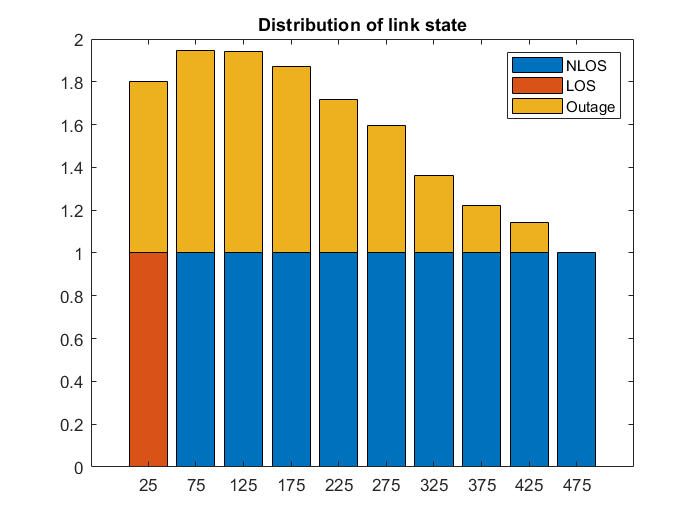


clf
bar(bincenter,cntnorm,'stacked')
title("Distribution of link state")
legend("NLOS","LOS","Outage")

## Predicting the link state

The model is given as 

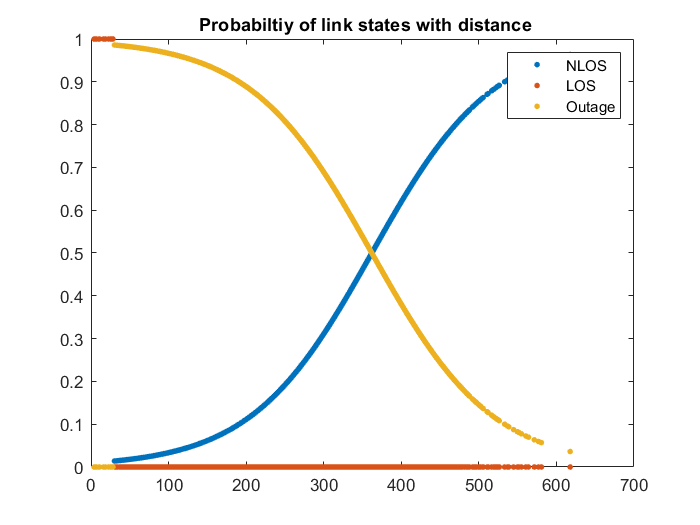

%   Using the mnrfit() method to find the coefficients B.  

B = mnrfit(dist1,linkstate +1);

% Using the mnrval() method to predict the probabilties of each class
% as a function of distance. 
pihat = mnrval(B,dist1);


clf
figure;

plot(dist1,pihat,"LineStyle","none","Marker",".","MarkerSize",10)
title ( " Probabiltiy of link states with distance")
legend("NLOS","LOS","Outage")